net = load("detector_nuova.mat").detector

net =   yolov4ObjectDetector with properties:

        Network: [1×1 dlnetwork]
    AnchorBoxes: {2×1 cell}
     ClassNames: {3×1 cell}
      InputSize: [960 1280 3]
      ModelName: 'tiny-yolov4-coco'


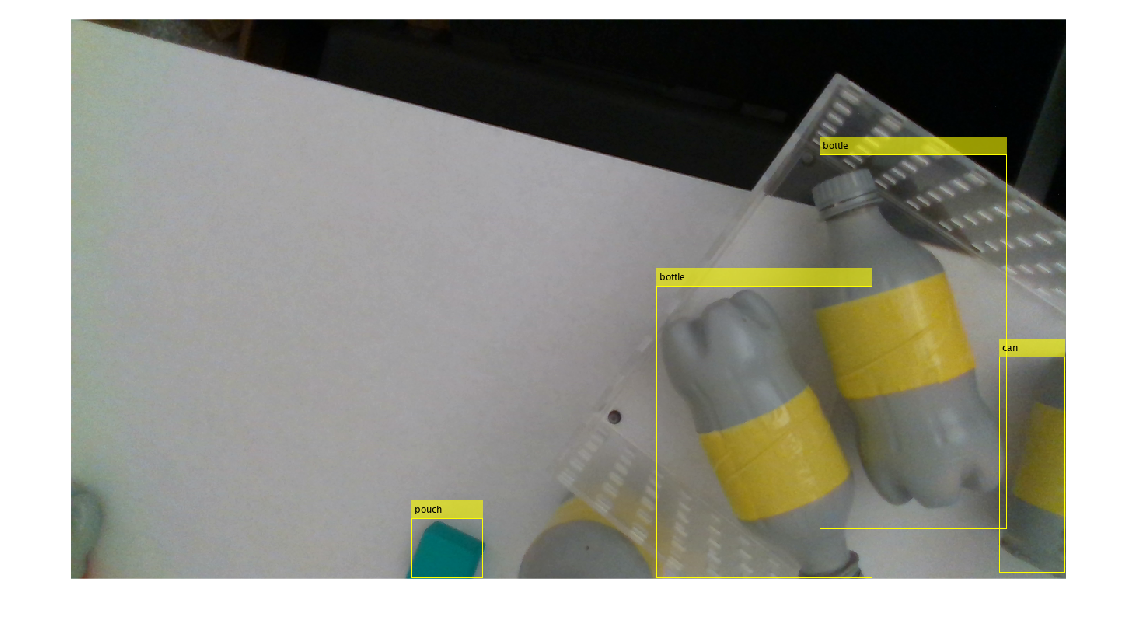

I = imread("arm_13.png");
[bboxes,scores,labels] = detect(detector,I);
I = insertObjectAnnotation(I,"rectangle",bboxes,labels);
figure
imshow(I)